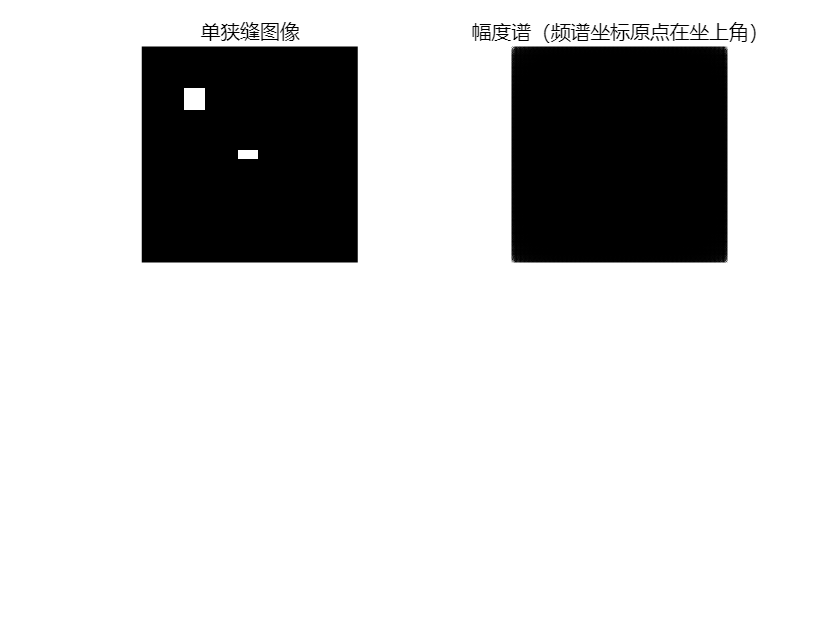

clear;
%对单缝进行快速傅里叶变换，以三种方式显示频谱，
%即：直接显示（坐标原点在左上角）；把坐标原点平
%移至中心后显示；以对数方式显示。
f=zeros(512,512);
f(246:266,230:276)=1;
f(100:150, 100:150) = 1;
subplot(221),imshow(f,[]),title('单狭缝图像')
F=fft2(f);  %对图像进行快速傅里叶变换
S=abs(F);
subplot(222),imshow(S,[]),title('幅度谱（频谱坐标原点在坐上角）')  %显示幅度谱

Fc=fftshift(F);  %把频谱坐标原点由左上角移至屏幕中央
subplot(223)
Fd=abs(Fc);
imshow(Fd,[])
ratio=max(Fd(:))/min(Fd(:))    

ratio = Inf

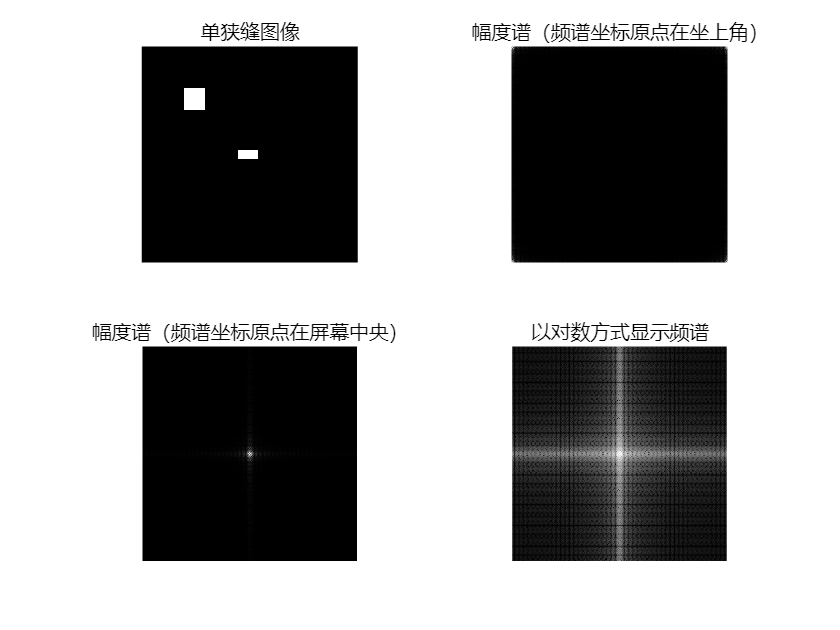

 %ratio = 2.3306e+007,动态范围太大，显示器无法正常显示
title('幅度谱（频谱坐标原点在屏幕中央）')
S2=log(1+abs(Fc));
subplot(224)
imshow(S2,[])
title('以对数方式显示频谱');

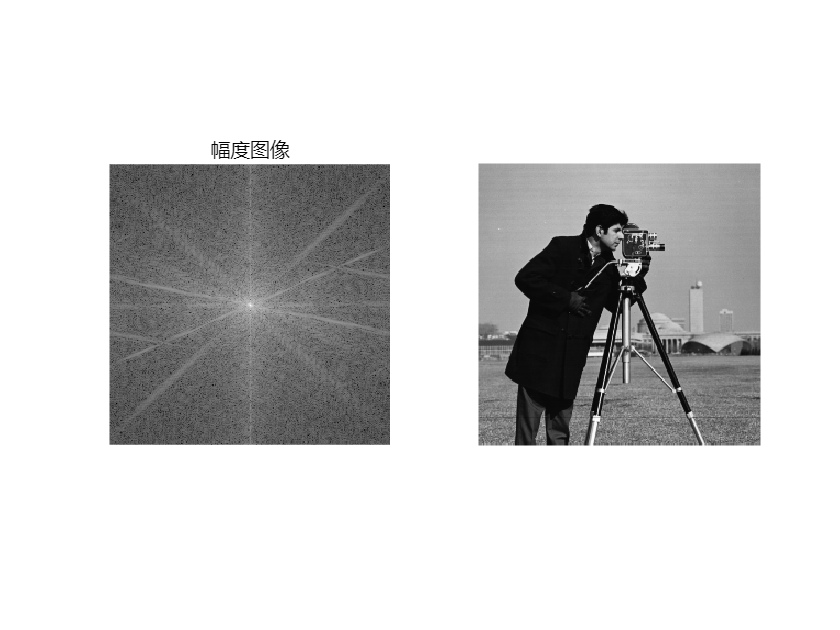

clear;
% 1)	读入cameraman.tif这幅图像，对其进行快速傅立叶变换，分别显示其幅度图像和相位图像。
I = imread('cameraman.tif');

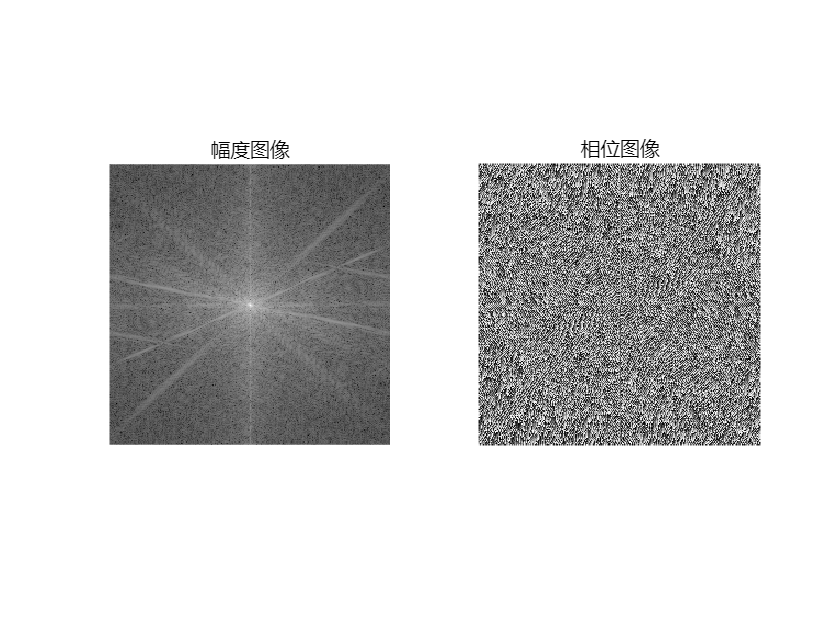






I_F = fft2(I); % 对图像进行快速傅立叶变换，元素为复数
I_F = fftshift(I_F); % 将零频率分量移动到图像中心
I_amp = log(1+abs(I_F)); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
I_phase = angle(I_F); % 计算相位
% imshow(I,[]) 显示灰度图像 I，根据 I 中的像素值范围对显示进行转换。imshow 使用 [min(I(:)) max(I(:))] 作为显示范围。imshow 将 I 中的最小值显示为黑色，将最大值显示为白色。
figure, subplot(1,2,1), imshow(I_amp, []), title('幅度图像'); 
subplot(1,2,2), imshow(I_phase, []), title('相位图像');

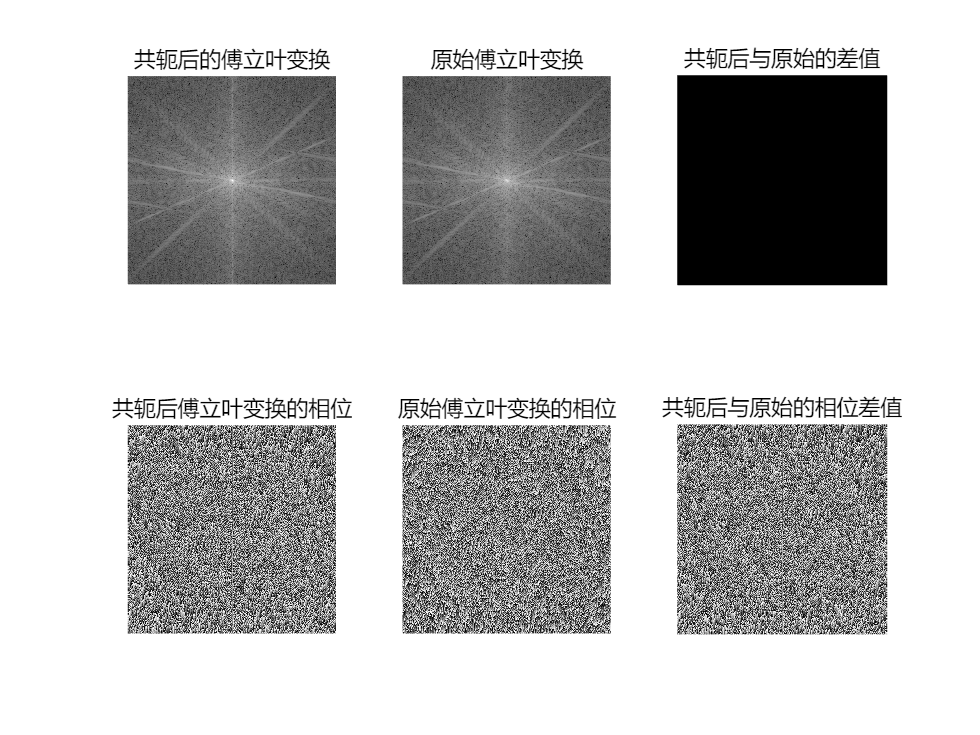


% 2)	将图像的傅立叶变换I_F置为其共轭后进行反变换，比较新生成图像与原始图像的差异。
I_F_conj = conj(I_F); % 共轭
% 比较I_F_conj与I_F
figure, subplot(2,3,1), imshow(log(1 + abs(I_F_conj)), []), title('共轭后的傅立叶变换');
subplot(2,3,2), imshow(log(1 + abs(I_F)), []), title('原始傅立叶变换');
subplot(2,3,3), imshow(log(1 + abs(I_F_conj)) - I_amp, []), title('共轭后与原始的差值');
subplot(2,3,4), imshow(angle(I_F_conj), []), title('共轭后傅立叶变换的相位');
subplot(2,3,5), imshow(angle(I_F), []), title('原始傅立叶变换的相位');
subplot(2,3,6), imshow(angle(I_F_conj) - I_phase, []), title('共轭后与原始的相位差值');

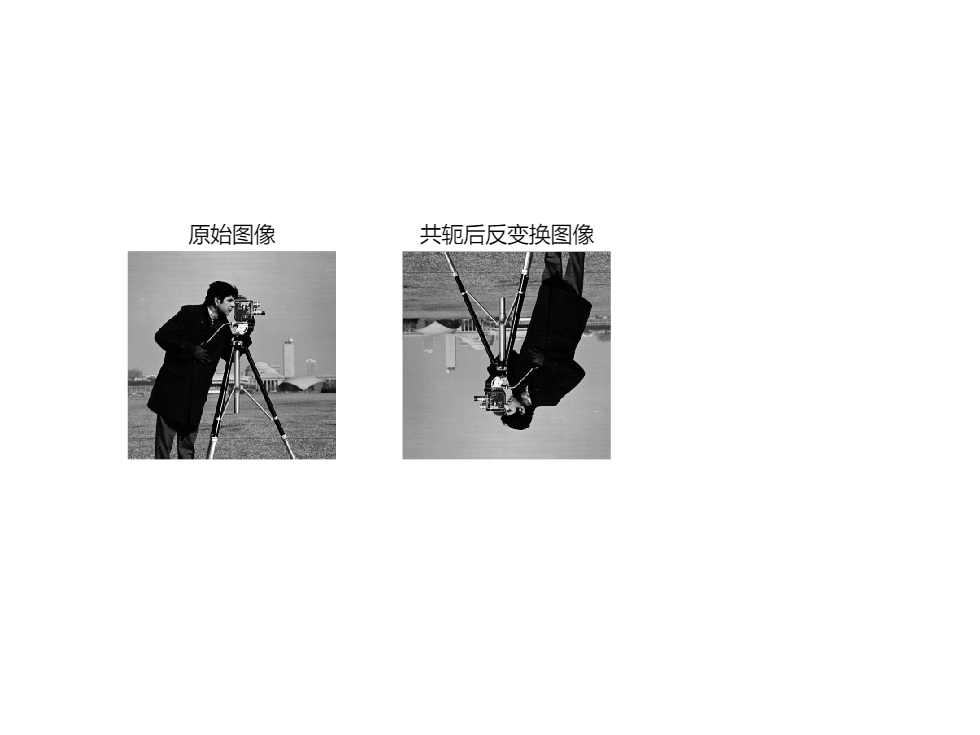

I_F_conj = ifftshift(I_F_conj); % 将零频率分量移动到图像左上角
% 反傅里叶变换
I_ifft = ifft2(I_F_conj);
figure, subplot(1,3,1), imshow(I, []), title('原始图像');
subplot(1,3,2), imshow(I_ifft, []), title('共轭后反变换图像');

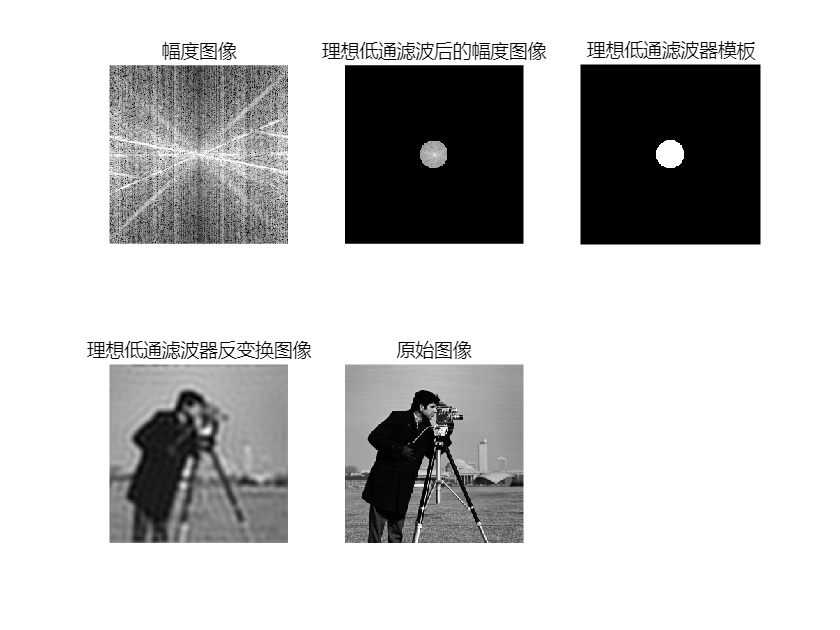


% 2.	平滑频域滤波
% 1)	设计理想低通滤波器、巴特沃斯低通滤波器和高斯低通滤波器，截至频率自选，分
% 别给出各种滤波器的透视图。
clear;
I = imread('cameraman.tif');
I_F = fft2(I); % 对图像进行快速傅立叶变换，元素为复数
I_F = fftshift(I_F); % 将零频率分量移动到图像中心
I_amp = log(1+abs(I_F)); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
I_amp = mapto01(I_amp); % 将图像的亮度范围映射到[0,1]之间

% 应用模板
D0 = 20;
h_ilpf = hilpf(I_amp, D0, 1); % 理想低通滤波器(截至频率为0.1)
I_ilpf = I_F .* h_ilpf;
I_ilpf_amp = log(1 + abs(I_ilpf));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_ilpf_amp, []), title('理想低通滤波后的幅度图像');
subplot(2,3,3), imshow(h_ilpf, []), title('理想低通滤波器模板');
I_ilpf_f = ifftshift(I_ilpf);
I_ifft = ifft2(I_ilpf_f);
I_ifft = real(I_ifft);
subplot(2,3,4), imshow(I_ifft, []), title('理想低通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

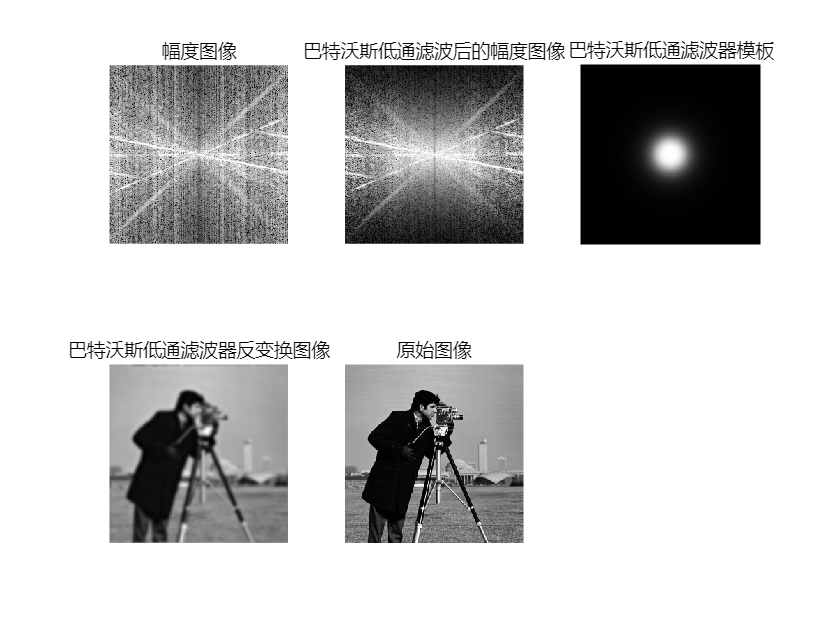



% 巴特沃斯低通滤波器
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_blpf = hblpf(I_amp, D0, 2, 1); % 巴特沃斯低通滤波器，2阶
I_blpf_amp = mapto01(log(1 + abs(I_F .* h_blpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_blpf_amp, []), title('巴特沃斯低通滤波后的幅度图像');
subplot(2,3,3), imshow(h_blpf, []), title('巴特沃斯低通滤波器模板');
I_blpf_if = real(ifft2(ifftshift(I_F .* h_blpf)));
subplot(2,3,4), imshow(I_blpf_if, []), title('巴特沃斯低通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

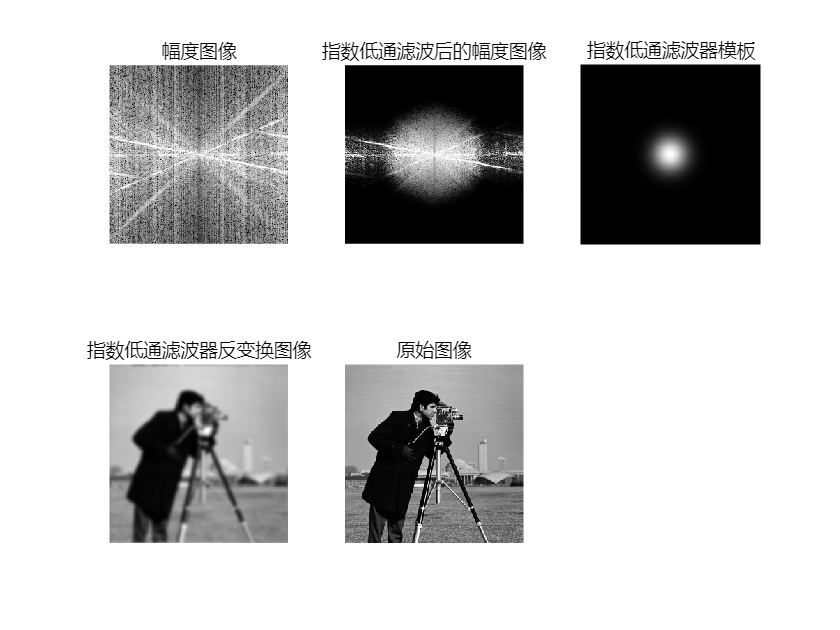


% 指数低通滤波器
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_elpf = helpf(I_amp, D0, 2, 1); % 指数低通滤波器，2阶
I_elpf_amp = mapto01(log(1 + abs(I_F .* h_elpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_elpf_amp, []), title('指数低通滤波后的幅度图像');
subplot(2,3,3), imshow(h_elpf, []), title('指数低通滤波器模板');
I_elpf_if = real(ifft2(ifftshift(I_F .* h_elpf)));
subplot(2,3,4), imshow(I_elpf_if, []), title('指数低通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

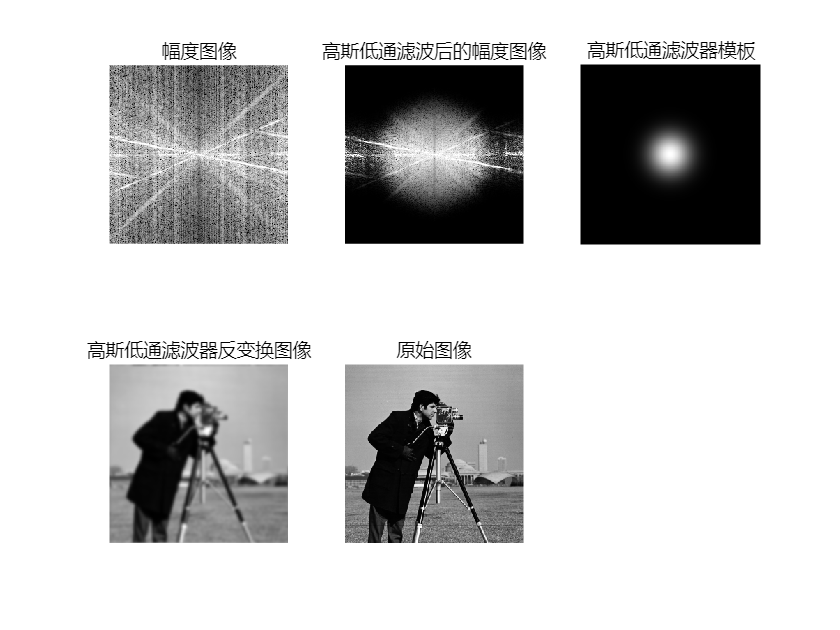


% 高斯低通滤高斯
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_glpf = hglpf(I_amp, D0, 1); % 高斯低通滤波器
I_glpf_amp = mapto01(log(1 + abs(I_F .* h_glpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_glpf_amp, []), title('高斯低通滤波后的幅度图像');
subplot(2,3,3), imshow(h_glpf, []), title('高斯低通滤波器模板');
I_glpf_if = real(ifft2(ifftshift(I_F .* h_glpf)));
subplot(2,3,4), imshow(I_glpf_if, []), title('高斯低通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

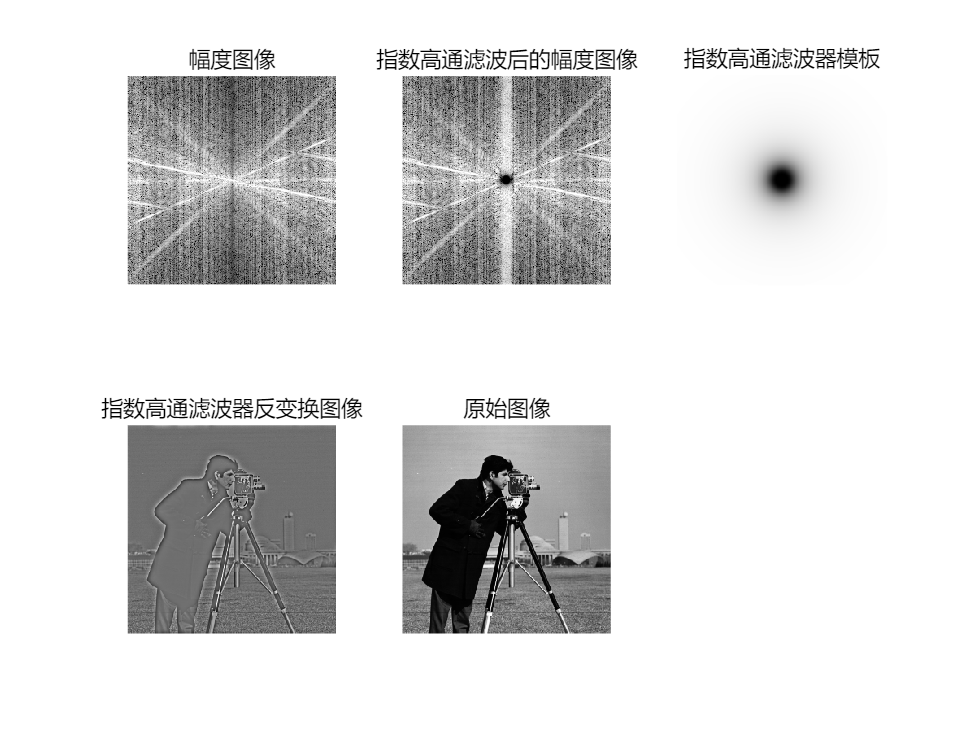

% 锐化滤波器
% 指数高通滤波器
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_elpf = helpf(I_amp, D0, 2, 0); % 指数高通滤波器，2阶
I_elpf_amp = mapto01(log(1 + abs(I_F .* h_elpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_elpf_amp, []), title('指数高通滤波后的幅度图像');
subplot(2,3,3), imshow(h_elpf, []), title('指数高通滤波器模板');
I_elpf_if = real(ifft2(ifftshift(I_F .* h_elpf)));
subplot(2,3,4), imshow(I_elpf_if, []), title('指数高通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

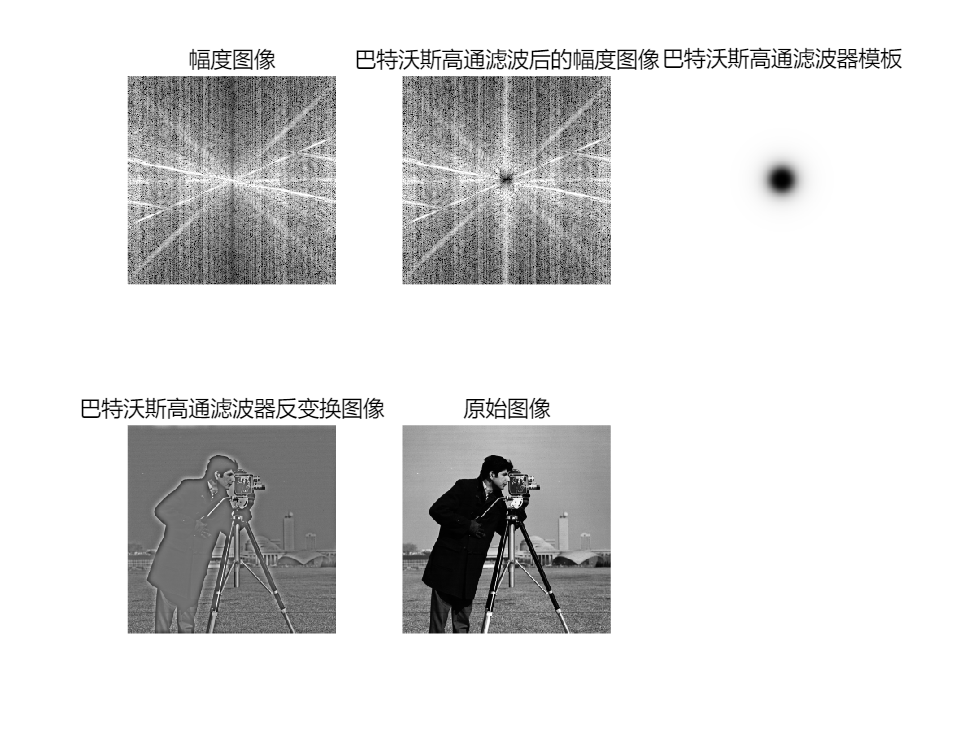

% 巴特沃斯高通滤波器
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_blpf = hblpf(I_amp, D0, 2, 0); % 巴特沃斯高通滤波器，2阶
I_blpf_amp = mapto01(log(1 + abs(I_F .* h_blpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_blpf_amp, []), title('巴特沃斯高通滤波后的幅度图像');
subplot(2,3,3), imshow(h_blpf, []), title('巴特沃斯高通滤波器模板');
I_blpf_if = real(ifft2(ifftshift(I_F .* h_blpf)));
subplot(2,3,4), imshow(I_blpf_if, []), title('巴特沃斯高通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

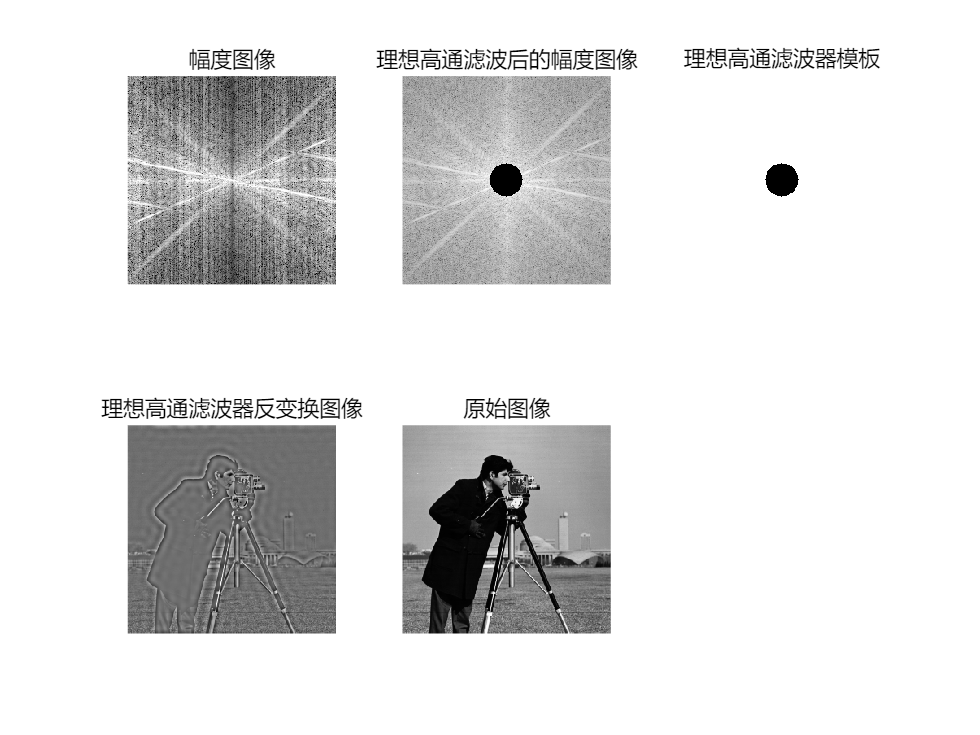

% 理想高通滤波
clear;
I = imread('cameraman.tif');
I_F = fft2(I); % 对图像进行快速傅立叶变换，元素为复数
I_F = fftshift(I_F); % 将零频率分量移动到图像中心
I_amp = log(1+abs(I_F)); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
I_amp = mapto01(I_amp); % 将图像的亮度范围映射到[0,1]之间

% 应用模板
D0 = 20;
h_ilpf = hilpf(I_amp, D0, 0); % 理想低通滤波器
I_ilpf = I_F .* h_ilpf;
I_ilpf_amp = log(1 + abs(I_ilpf));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_ilpf_amp, []), title('理想高通滤波后的幅度图像');
subplot(2,3,3), imshow(h_ilpf, []), title('理想高通滤波器模板');
I_ilpf_f = ifftshift(I_ilpf);
I_ifft = ifft2(I_ilpf_f);
I_ifft = real(I_ifft);
subplot(2,3,4), imshow(I_ifft, []), title('理想高通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');

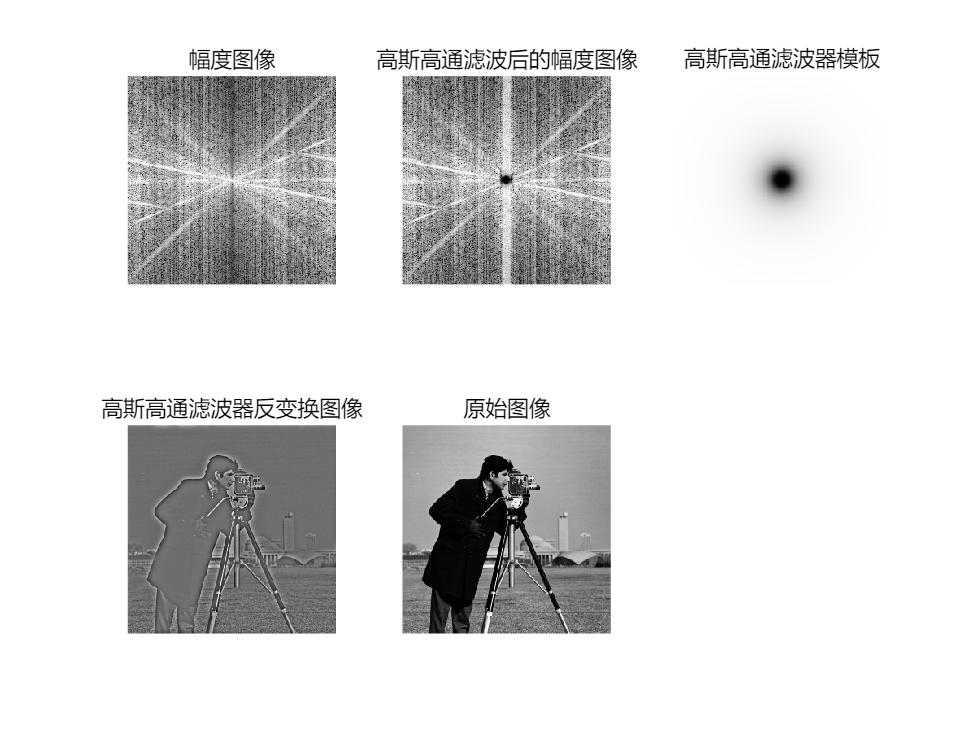

% 高斯高通滤高斯
clear;
I = imread('cameraman.tif');
I_F = fftshift(fft2(I)); % 将零频率分量移动到图像中心
I_amp = mapto01(log(1+abs(I_F))); % 缩短图像的亮度范围以便于显示, 将暗部区域对比度增强，将亮部区域对比度降低，最终使得图像的暗部细节更加清晰
D0 = 20;
h_glpf = hglpf(I_amp, D0, 0); % 高斯低通滤波器
I_glpf_amp = mapto01(log(1 + abs(I_F .* h_glpf)));
figure, subplot(2,3,1), imshow(I_amp, []), title('幅度图像');
subplot(2,3,2), imshow(I_glpf_amp, []), title('高斯高通滤波后的幅度图像');
subplot(2,3,3), imshow(h_glpf, []), title('高斯高通滤波器模板');
I_glpf_if = real(ifft2(ifftshift(I_F .* h_glpf)));
subplot(2,3,4), imshow(I_glpf_if, []), title('高斯高通滤波器反变换图像');
subplot(2,3,5), imshow(I, []), title('原始图像');